clear

#### Global settings:

Here should be specifies the TFP type on which to calculate the productivity process parameters: TFP or TFP corrected for utilisation (Fernald, 2014).

format long g           % Set general rule for lenght of values displayed
smoothing = 1600;       % Set global value for smoothing parameter
which_TFP = 'DTFP';     % TFP type selection: either 'DTFP' or 'DTFP_UTIL' 

#### Preparing data:

Here I run an ad hoc function in order to create align Fernald table format to FRED ones. This helps streamline the subsequent importation process.

x_extract_tfp_quarterly;

# 1) Calculate empirical moments

In this section I calculate moments for empirical time series of the main variables populating the RBC model. Those moments will be the benchmark against which model simulation will be evaluated.

#### Import data:

I import data from different datasets from the Federal Reserve of San Francisco platform FRED and from Fernald (Fernald, 2014): non-istitutionalised population aged 16 or older (POP), GDP deflator (GDPDEF), gross domestic product (Y), fixed private investment (FPI), private consumption of durable goods (PCDG), private consumption of services (PCESV), private consumption of non-durable goods (PCND), labor hours in the non-farm sector (N), total factor productivity (DTFP) and total factor productivity corrected for utilisation (DTFP_UTIL). The chosen time frame is: quarter 1 - 1948, to quarter 4 - 2019.  

sheet = 'Quarterly';
start_quarter = datetime('01-Jan-1948');
end_quarter = datetime('01-Oct-2019');
quarters = x_count_quarters(start_quarter, end_quarter);   % Runs ad-hoc function that counts number of quarters

POP_data    = readtable('CNP16OV.xlsx', 'Sheet', sheet);
POP         = POP_data.CNP16OV(POP_data.observation_date >= start_quarter & POP_data.observation_date <= end_quarter);

GDPDEF_data = readtable('GDPDEF.xlsx', 'Sheet', sheet);
GDPDEF      = GDPDEF_data.GDPDEF(GDPDEF_data.observation_date >= start_quarter & GDPDEF_data.observation_date <= end_quarter);

GDP_data    = readtable('GDP.xlsx', 'Sheet', sheet);
Y           = GDP_data.GDP(GDP_data.observation_date >= start_quarter & GDP_data.observation_date <= end_quarter);

FPI_data    = readtable('FPI.xlsx', 'Sheet', sheet);
FPI         = FPI_data.FPI(FPI_data.observation_date >= start_quarter & FPI_data.observation_date <= end_quarter);

PCDG_data   = readtable('PCDG.xlsx', 'Sheet', sheet);
PCDG        = PCDG_data.PCDG(PCDG_data.observation_date >= start_quarter & PCDG_data.observation_date <= end_quarter);

PCESV_data  = readtable('PCESV.xlsx', 'Sheet', sheet);
PCESV       = PCESV_data.PCESV(PCESV_data.observation_date >= start_quarter & PCESV_data.observation_date <= end_quarter);

PCND_data   = readtable('PCND.xlsx', 'Sheet', sheet);
PCND        = PCND_data.PCND(PCND_data.observation_date >= start_quarter & PCND_data.observation_date <= end_quarter);

HOANBS_data = readtable('HOANBS.xlsx', 'Sheet', sheet);
N           = HOANBS_data.HOANBS(HOANBS_data.observation_date >= start_quarter & HOANBS_data.observation_date <= end_quarter);

DTFP_data   = readtable('DTFP.xlsx', 'Sheet', sheet);
DTFP        = DTFP_data.DTFP(DTFP_data.observation_date >= start_quarter & DTFP_data.observation_date <= end_quarter);

DTFP_U_data = readtable('DTFP_UTIL.xlsx', 'Sheet', sheet);
DTFP_UTIL   = DTFP_U_data.DTFP_UTIL(DTFP_U_data.observation_date >= start_quarter & DTFP_U_data.observation_date <= end_quarter);

#### TFP data transformation:

Data from Fernald are in quarterly % change rates, annualised = 400(lnA_t - lnA_{t-1}. I remove percent and annualisation, and cumulatively sum the values to turn the TFP series (both standard and util-corrected) in quarterly log-levels. 

% for DTFP
DTFP        = DTFP/400;
logTFP      = cumsum(DTFP);

% for DTFP_UTIL
DTFP_UTIL   = DTFP_UTIL/400;
logTFP_U    = cumsum(DTFP_UTIL);

#### TFP parameters estimation:

I estimate persistance and standard deviaton of shocks of the productivity process. I linearly detrend the serie, to comply with the productivity process designed in the model. I create lagged series so to have istances of a_t and a_{t-1}. I get persistance trough OLS estimation, impliying an AR(1) process for a_t, with no constant value. I define the productivity shocks as the estimated error term of the regression. I get the standard deviation of the shocks by the OLS estimator of the error variance.

TFP_cycle   = detrend(logTFP, 1);
TFP_U_cycle = detrend(logTFP_U, 1);

if strcmp(which_TFP, 'DTFP_UTIL') == 1   % Given the selected TFP type defines 'a' with different data 
    a_t     = TFP_U_cycle(2:end);
    a_lag   = TFP_U_cycle(1:end-1);
else
    a_t     = TFP_cycle(2:end);
    a_lag   = TFP_cycle(1:end-1);
end

rho_hat     = (a_lag' * a_t) / (a_lag' * a_lag);                % Estimated persistence
E_cycle     = a_t - rho_hat * a_lag;                            % Estimated shocks
sigma_hat   = sqrt((E_cycle' * E_cycle) / (length(a_t) - 1));   % Estimated standard deviation of the shocks

#### Trasformations to the remaining series:

The series have to go trough some trasformation so that they can be comparable to the ones simulated by the model. Fixed private investment (FPI) and private consumption of durable goods (PCDG) are summed to have investment (I). Private consumption of services (PCESV) and non-durable goods (PCND) are summed together to have consumption (C). Gross domestic product (Y), investment and consumption come in nominal terms so have to be deflated (/GDPDEF). I take natural logs of all the series and calculate the per capita values by subtracting log population. Finally all series are de trended with the Hodrick - Prescott filter, with smoothing = 1600 (Hodrick, 1997). All the series, relevant for the model evaluation, are now in real, per-capita, HP-filtered, log-levels. 

I = PCDG + FPI;
C = PCND + PCESV;

rY = Y ./ GDPDEF;
rI = I ./ GDPDEF;
rC = C ./ GDPDEF;

logPOP  = log(POP);
logrY   = log(rY);
logrI   = log(rI);
logrC   = log(rC);
logN    = log(N);

pcY = logrY - logPOP;
pcI = logrI - logPOP;
pcC = logrC - logPOP;
pcN = logN  - logPOP;

[Y_trend, Y_cycle] = hpfilter(pcY, "Smoothing", smoothing);
[I_trend, I_cycle] = hpfilter(pcI, "Smoothing", smoothing);
[C_trend, C_cycle] = hpfilter(pcC, "Smoothing", smoothing);
[N_trend, N_cycle] = hpfilter(pcN, "Smoothing", smoothing);

Y_cycle = Y_cycle';
I_cycle = I_cycle';
C_cycle = C_cycle';
N_cycle = N_cycle';

#### Calculation of empirical moments:

I calculate the main empirical moments which are going to be used as benchmarks to evaluate model simulation performance: standard deviation (_sd), standard deviation relative to Y (_onY_sd), first-order autocorrelation (_ac) and contemporaneous correlation with Y (_Yc). I conclude the section by  building a table displaying the moments.

Y_sd = std(Y_cycle, 0, 2);
I_sd = std(I_cycle, 0, 2);
C_sd = std(C_cycle, 0, 2);
N_sd = std(N_cycle, 0, 2);

Y_onY_sd = Y_sd/Y_sd;
I_onY_sd = I_sd/Y_sd;
C_onY_sd = C_sd/Y_sd;
N_onY_sd = N_sd/Y_sd;

Y_ac_step = autocorr(Y_cycle',"NumLags",1);
Y_ac = Y_ac_step(2);
I_ac_step = autocorr(I_cycle',"NumLags",1);
I_ac = I_ac_step(2);
C_ac_step = autocorr(C_cycle',"NumLags",1);
C_ac = C_ac_step(2);
N_ac_step = autocorr(N_cycle',"NumLags",1);
N_ac = N_ac_step(2);

Y_Yc_step = xcorr(Y_cycle, Y_cycle,'coeff');
Y_Yc = Y_Yc_step(quarters);
I_Yc_step = xcorr(I_cycle, Y_cycle,'coeff');
I_Yc = I_Yc_step(quarters);
C_Yc_step = xcorr(C_cycle, Y_cycle,'coeff');
C_Yc = C_Yc_step(quarters);
N_Yc_step = xcorr(N_cycle, Y_cycle,'coeff');
N_Yc = N_Yc_step(quarters);

#### Empirical moments table:          

moments = [
    Y_sd, Y_onY_sd, Y_Yc, Y_ac;
    C_sd, C_onY_sd, C_Yc, C_ac;
    I_sd, I_onY_sd, I_Yc, I_ac;
    N_sd, N_onY_sd, N_Yc, N_ac
];
  
moments = round(moments, 2);        % Rounding to 2nd decimal
vars    = {'Y','C','I','N'}; 
etable  = array2table(moments, ...
    'VariableNames', {'E.sd','E.onY_sd','E.Yc','E.ac'}, ...
    'RowNames', vars);
disp(etable);

         E.sd    E.onY_sd    E.Yc    E.ac
         ____    ________    ____    ____
    Y    0.02         1         1    0.85
    C    0.01      0.52      0.77    0.81
    I    0.04      2.75      0.76    0.87
    N    0.02      1.18      0.87     0.9


# 2) Dynare-simulated moments

In this section I calibrate, resolve and simulate the RBC model by running a Dynare .mod file and calculate moments on the Dynare-simulated time series.

#### Settings and running the .mod file:

In this section we set and run the Dynare .mod file. The file contains the necessary design to calibrate, solve and simulate the baseline RBC model, described in the Model section. The .mod file content is separately commented. The file has been mostly fed standard calibrated-parameters from literature. Parameters for the productivity process are estimated on empirical data in section 1 and pass directly to the .mod file. The .mod file generates policy functions by n-ordered Taylor approximation. The order of approximation is decided here and passed onto the .mod file, as is the possibility of having the simulated data be HP-filtered and the number of periods Dynare will consider to calculate the moments. The Dynare results are going to be printed under the following cell.

stoch_simul_periods = quarters;     % Passes number of empirical quarters
stoch_simul_order   = 4;            % Order of the Taylor approximation
stoch_simul_hp      = 1;            % HP-filtering: 1 = on, 0 = off

eval(sprintf(['dynare RBC.mod noclearall ' ...
    '-Dstoch_simul_periods=%d -Dstoch_simul_order=%d -Dstoch_simul_hp=%d -Dhp_smooth=%d'], ...
    stoch_simul_periods, stoch_simul_order, stoch_simul_hp, smoothing));

Starting Dynare (version 6.5).
Calling Dynare with arguments: noclearall -Dstoch_simul_periods=288 -Dstoch_simul_order=4 -Dstoch_simul_hp=1 -Dhp_smooth=1600
Starting preprocessing of the model file ... 
Found 16 equation(s). 
Evaluating expressions... 
Computing static model derivatives (order 1). 
Normalizing the static model... 
Finding the optimal block decomposition of the static model... 
4 block(s) found: 
  3 recursive block(s) and 1 simultaneous block(s). 
  the largest simultaneous block has 7 equation(s) 
                                 and 7 feedback variable(s). 
Computing dynamic model derivatives (order 4). 
Normalizing the dynamic model... 
Finding the optimal block decomposition of the dynamic model... 
4 block(s) found: 
  3 recursive block(s) and 1 simultaneous block(s). 
  the largest simultaneous block has 7 equation(s) 
                                 and 7 feedback variable(s). 
Preprocessing completed. 
Preprocessing time: 0h00m00s.

MODEL SUMMARY

  Number of 

#### Retriving variable indexes:

I retrieve the index number for variables of interest, from the order of declaration, saved by Dynare in a ordered vector (M_.endo_names). I retrieve the index for the same series considered for the empirical moments: Y, I, C, N. All series are theoretically designed as real, per-capita, log-levels and after simulation are HP-filtered. Therefore comply in unit and scale with empirical ones.

ilogY = find(strcmp(M_.endo_names, 'logY'));
ilogI = find(strcmp(M_.endo_names, 'logI'));
ilogC = find(strcmp(M_.endo_names, 'logC'));
ilogN = find(strcmp(M_.endo_names, 'logN'));

#### Reporting Dynare-generated moments:

Here I retrieve the moments for the dynare-simulated time series. I use the indexes to locate the relevant moments from the matrices of results that Dynare produces (oo_.var, oo_.autocorr, oo_.contemporaneous_correlation) since, in those matrices, values are stored in declaration order. The moments are directly calculated by Dynare and I just retrieve them, beside relative standard deviation (d_onY_sd) which anyhow is calculated on Dynare's standard deviations (d_sd). As before, at last, I build a table displaying the moments.

Yd_sd = sqrt(oo_.var(ilogY,ilogY));
Id_sd = sqrt(oo_.var(ilogI,ilogI));
Cd_sd = sqrt(oo_.var(ilogC,ilogC));
Nd_sd = sqrt(oo_.var(ilogN,ilogN));

Yd_onY_sd = Yd_sd / Yd_sd;
Id_onY_sd = Id_sd / Yd_sd;
Cd_onY_sd = Cd_sd / Yd_sd;
Nd_onY_sd = Nd_sd / Yd_sd;

Yd_ac = oo_.autocorr{1}(ilogY,ilogY);
Id_ac = oo_.autocorr{1}(ilogI,ilogI);
Cd_ac = oo_.autocorr{1}(ilogC,ilogC);
Nd_ac = oo_.autocorr{1}(ilogN,ilogN);

Yd_Yc = oo_.contemporaneous_correlation(ilogY, ilogY);
Id_Yc = oo_.contemporaneous_correlation(ilogI, ilogY);
Cd_Yc = oo_.contemporaneous_correlation(ilogC, ilogY);
Nd_Yc = oo_.contemporaneous_correlation(ilogN, ilogY);

moments = [
    Yd_sd, Yd_onY_sd, Yd_Yc, Yd_ac;
    Cd_sd, Cd_onY_sd, Cd_Yc, Cd_ac;
    Id_sd, Id_onY_sd, Id_Yc, Id_ac;
    Nd_sd, Nd_onY_sd, Nd_Yc, Nd_ac
];

moments = round(moments, 2);
vars = {'Y','C','I','N'};
dtable = array2table(moments, ...
    'VariableNames', {'D.sd','D.onY_sd','D.Yc','D.ac'}, ...
    'RowNames', vars);
disp(dtable);

         D.sd    D.onY_sd    D.Yc    D.ac
         ____    ________    ____    ____
    Y    0.01         1         1    0.66
    C    0.01      0.41      0.95    0.73
    I    0.05      4.04      0.98    0.65
    N    0.01      0.43      0.98    0.64


# 3) Scratch-simulated moments

In this section I calculate moments from scratch, on a simulated time series which is built from scratch by using the Dynare-calculated policy functions and steady states and the empirically estimated productivity shocks. 

#### Running the simult_ procedure:

I run the helper function, simult_. Simult_ is a Dynare-distributed Matlab routine. It takes as arguments: the computed decision rules (`oo_.dr`), an initial condition (here the steady state `oo_.dr.ys`), a path of exogenous shocks (here the empirically estimated shocks E_cycle) and the requested approximation order (here stoch_simul_order defined in the previous section). It uses the arguments to produce simulated time series for the endogenous variables. The main difference respect to Dynare-produced series, is that, in this case, the shocks are empirically estimated instead of randomly drawn. A matrix of time series is created (SIM).

sim = simult_(M_, options_, oo_.dr.ys, oo_.dr, E_cycle, stoch_simul_order);

#### Dropping the initial conditions:

Simult_ stores the initial conditions as the first values in the matrix of time series. I drop those initial values cause they are arbitrary (here set to the steady state) and would have no relation to the empirical first-period values: they would not be comparable. The other periods would be comparable since they are calculated taking into account the estimated shocks. Anyhow, later, I will drop the first column from the empirical series too. The reason is that in the estimated residuals serie the first occurance can't be calculated, by construction ($\bar{u_t}=x_t-\bar{\rho }x_{t-1}$: we only have a value for $\bar{u}_t$ for $t=>2$ $u_1$ is not defined).�

sim = sim(:,2:end); 

#### Locate and transform the series:

I locate relevant indexes and apply the HP-filter.

Ys = sim(ilogY,:);
Cs = sim(ilogC,:);
Is = sim(ilogI,:);
Ns = sim(ilogN,:);

[Ys_trend, Ys_cycle] = hpfilter(Ys, "Smoothing", smoothing);
[Cs_trend, Cs_cycle] = hpfilter(Cs, "Smoothing", smoothing);
[Is_trend, Is_cycle] = hpfilter(Is, "Smoothing", smoothing);
[Ns_trend, Ns_cycle] = hpfilter(Ns, "Smoothing", smoothing);

Ys_cycle = Ys_cycle'; 
Cs_cycle = Cs_cycle';
Is_cycle = Is_cycle';
Ns_cycle = Ns_cycle';

#### Calculation of moments simulated from scratch:

I calculate moments in the same way, and for the same variables, I did in the first section. I display the final results in a table, as usual.

Ys_sd = std(Ys_cycle, 0, 2);
Is_sd = std(Is_cycle, 0, 2);
Cs_sd = std(Cs_cycle, 0, 2);
Ns_sd = std(Ns_cycle, 0, 2);

Ys_onY_sd = Ys_sd/Ys_sd;
Is_onY_sd = Is_sd/Ys_sd;
Cs_onY_sd = Cs_sd/Ys_sd;
Ns_onY_sd = Ns_sd/Ys_sd;

Ys_ac_step = autocorr(Ys_cycle',"NumLags",1);
Ys_ac = Ys_ac_step(2);
Is_ac_step = autocorr(Is_cycle',"NumLags",1);
Is_ac = Is_ac_step(2);
Cs_ac_step = autocorr(Cs_cycle',"NumLags",1);
Cs_ac = Cs_ac_step(2);
Ns_ac_step = autocorr(Ns_cycle',"NumLags",1);
Ns_ac = Ns_ac_step(2);

Ys_Yc_step = xcorr(Ys_cycle, Ys_cycle,'coeff');
Ys_Yc = Ys_Yc_step(quarters);
Is_Yc_step = xcorr(Is_cycle, Ys_cycle,'coeff');
Is_Yc = Is_Yc_step(quarters);
Cs_Yc_step = xcorr(Cs_cycle, Ys_cycle,'coeff');
Cs_Yc = Cs_Yc_step(quarters);
Ns_Yc_step = xcorr(Ns_cycle, Ys_cycle,'coeff');
Ns_Yc = Ns_Yc_step(quarters);

moments = [
    Ys_sd, Ys_onY_sd, Ys_Yc, Ys_ac;
    Cs_sd, Cs_onY_sd, Cs_Yc, Cs_ac;
    Is_sd, Is_onY_sd, Is_Yc, Is_ac;
    Ns_sd, Ns_onY_sd, Ns_Yc, Ns_ac
];

moments = round(moments, 2);
vars = {'Y','C','I','N'};
stable = array2table(moments, ...
    'VariableNames', {'S.sd','S.onY_sd','S.Yc','S.ac'}, ...
    'RowNames', vars);
disp(stable);

         S.sd    S.onY_sd    S.Yc    S.ac
         ____    ________    ____    ____
    Y    0.02         1      0.78    0.78
    C    0.01      0.41      0.84    0.82
    I    0.07      3.98      0.73    0.78
    N    0.01      0.43       0.7    0.78


# 4) Moments comparison

Here I produce a comparison table, displaying all the moments calculated so far.  

T = [etable,dtable,stable];
vn = T.Properties.VariableNames;
suf = {'.sd','.onY_sd','.Yc','.ac'};
pref = {'E.','D.','S.'};
cols = {};
for i=1:numel(suf)
    g = {};
    for j=1:numel(pref)
        nm = [pref{j} suf{i}];
        k = find(strcmp(vn,nm),1);
        if k, g{end+1}=vn{k}; end
    end
    if isempty(g), g = vn(endsWith(vn,suf{i})); end
    cols = [cols,g];
end
combined = array2table(T{:,cols}, 'VariableNames', cols, 'RowNames', T.Properties.RowNames);
disp(combined);

         E.sd    D.sd    S.sd    E.onY_sd    D.onY_sd    S.onY_sd    E.Yc    D.Yc    S.Yc    E.ac    D.ac    S.ac
         ____    ____    ____    ________    ________    ________    ____    ____    ____    ____    ____    ____
    Y    0.02    0.01    0.02         1           1           1         1       1    0.78    0.85    0.66    0.78
    C    0.01    0.01    0.01      0.52        0.41        0.41      0.77    0.95    0.84    0.81    0.73    0.82
    I    0.04    0.05    0.07      2.75        4.04        3.98      0.76    0.98    

All the tables produced in the model are exported in latex format.

x_write_latex_table(etable,   'y_etable.tex',   'Empirical Moments',    'tab:emp');
x_write_latex_table(dtable,   'y_dtable.tex',   'Dynare Moments',       'tab:dyn');
x_write_latex_table(stable,   'y_stable.tex',   'Scratch Moments',      'tab:scr');
x_write_latex_table(combined, 'y_combined.tex', 'Combined Moments',     'tab:combined');

# 5) Graphical comparison

In this section I compare the graphical rapresentation of empirical and scratch-simulated time series, to visually evaluate the fit.

#### Trim the empirical series:

I drop the first column from the empirical series. As said in section 3, the reason is that the estimated residuals miss the first-period value. After dropping the first occurance of the empirical serie the two series match in size and are aligne time-wise. 

dates = (start_quarter:calquarters(1):end_quarter)';
dates_trim = dates(2:end);

% Trim empirical to start at Q2
Y_trim = Y_cycle(2:end);
C_trim = C_cycle(2:end);
I_trim = I_cycle(2:end);
N_trim = N_cycle(2:end);

#### Plotting timeseries for each variable:

I produce individual graphs for each variable, simultaneously displaying the empirical and simulated time series. 

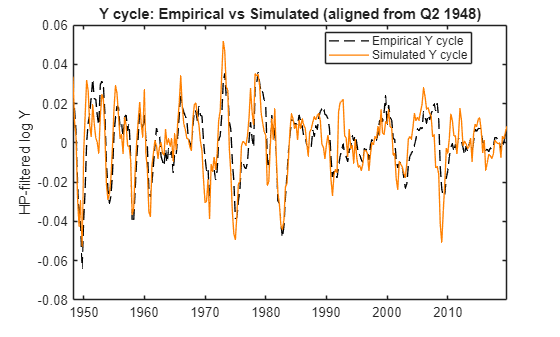

figure;
plot(dates_trim, Y_trim, 'k--', 'LineWidth', 1); hold on;
plot(dates_trim, Ys_cycle, 'b-', 'LineWidth', 1, 'Color', [1 0.5 0]);
grid on;
legend('Empirical Y cycle', 'Simulated Y cycle', 'Location', 'best');
title('Y cycle: Empirical vs Simulated (aligned from Q2 1948)');
ylabel('HP-filtered log Y');
grid off;
set(gcf, 'Color', 'w');
exportgraphics(gcf, 'z_Y.png', 'Resolution', 1000);

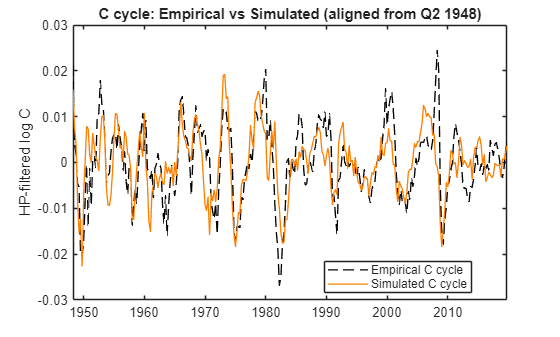

figure;
plot(dates_trim, C_trim, 'k--', 'LineWidth', 1); hold on;
plot(dates_trim, Cs_cycle, 'b-', 'LineWidth', 1, 'Color', [1 0.5 0]);
grid on;
legend('Empirical C cycle', 'Simulated C cycle', 'Location', 'best');
title('C cycle: Empirical vs Simulated (aligned from Q2 1948)');
ylabel('HP-filtered log C');
grid off;
set(gcf, 'Color', 'w');
exportgraphics(gcf, 'z_C.png', 'Resolution', 1000);

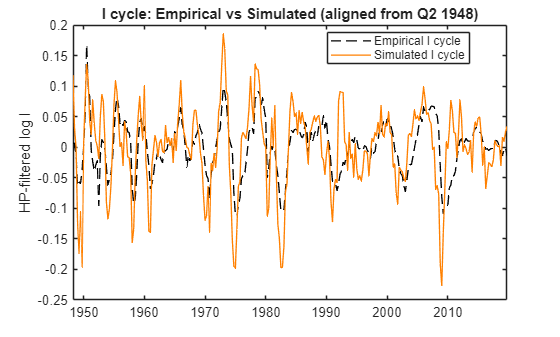

figure;
plot(dates_trim, I_trim, 'k--', 'LineWidth', 1); hold on;
plot(dates_trim, Is_cycle, 'b-', 'LineWidth', 1, 'Color', [1 0.5 0]);
grid on;
legend('Empirical I cycle', 'Simulated I cycle', 'Location', 'best');
title('I cycle: Empirical vs Simulated (aligned from Q2 1948)');
ylabel('HP-filtered log I');
grid off;
set(gcf, 'Color', 'w');
exportgraphics(gcf, 'z_I.png', 'Resolution', 1000);

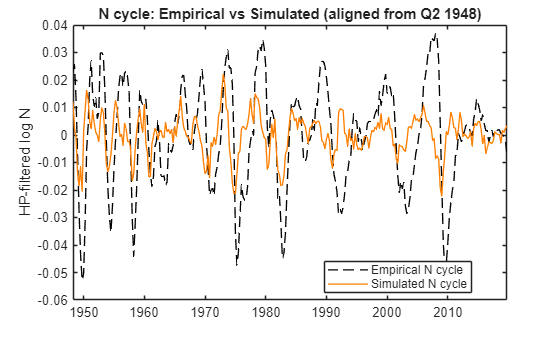

figure;
plot(dates_trim, N_trim, 'k--', 'LineWidth', 1); hold on;
plot(dates_trim, Ns_cycle, 'b-', 'LineWidth', 1, 'Color', [1 0.5 0]);
grid on;
legend('Empirical N cycle', 'Simulated N cycle', 'Location', 'best');
title('N cycle: Empirical vs Simulated (aligned from Q2 1948)');
ylabel('HP-filtered log N');
grid off;
set(gcf, 'Color', 'w');
exportgraphics(gcf, 'z_N.png', 'Resolution', 1000);